# Compare reconstruction and original time series

clear; close all; clc;

## Covariance matrix - Picture 1

Ковариационная матрица

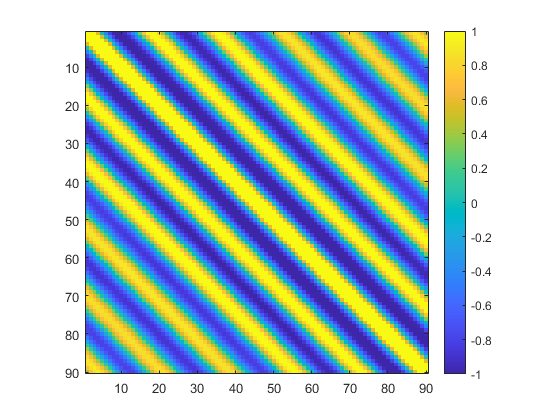

    C=loadData(1,"C");
    figure();
    set(gcf,'name','Covariance matrix');
    clf;
    imagesc(C);
    axis square;
    set(gca,'clim',[-1 1]);
    colorbar;

## Eigenvalues - Picture 2

Собственный вектор

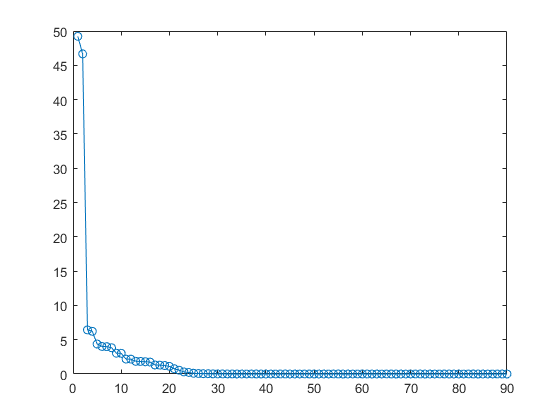

    LBD=loadData(2,"LBD");
    figure();
    set(gcf,'name','Eigenvalues')
    clf;
    plot(LBD,'o-');

## Original time series and reconstruction - Picture 3

Первоначальный временной ряд и его реконструкция для sET12

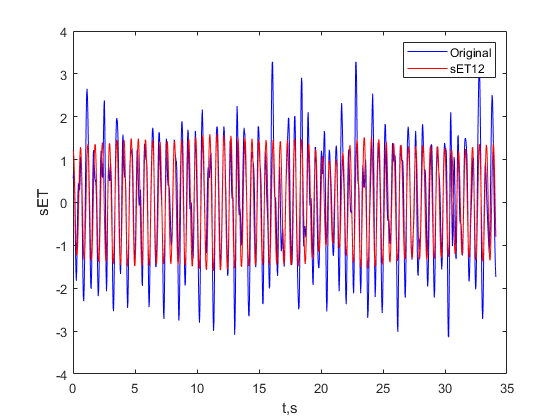

    seg = 100; % номер сегмента pw для визуализации
    win = 1024;
    spw=loadData(3,"spw");
    tim=loadData(3,"tim")';
    sET12=loadData(3,"sET12");
    figure();
    set(gcf,'name','Original time series and reconstruction'); clf;
    plot(tim(1:win),spw(:,seg),'b-',tim(1:win),sET12(:,seg),'r-');
    legend('Original','sET12'); xlabel("t,s",'interp','none'); ylabel("sET",'interp','none');

## Original time series and reconstruction - Picture 4

Первоначальный временной ряд и его реконструкция для sET34

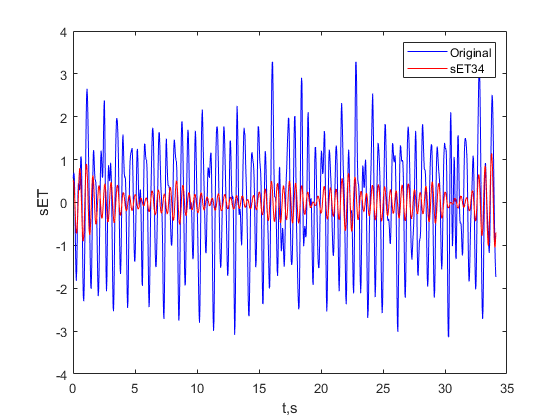

    seg = 100; % номер сегмента pw для визуализации
    win = 1024;
    spw=loadData(4,"spw");
    tim=loadData(4,"tim")';
    sET34=loadData(4,"sET34");
    figure();
    set(gcf,'name','Original time series and reconstruction'); clf;
    plot(tim(1:win),spw(:,seg),'b-',tim(1:win),sET34(:,seg),'r-');
    legend('Original','sET34'); xlabel("t,s",'interp','none'); ylabel("sET",'interp','none');

## Визуализация АКФ сингулярных троек для сегментов pw - Picture 5

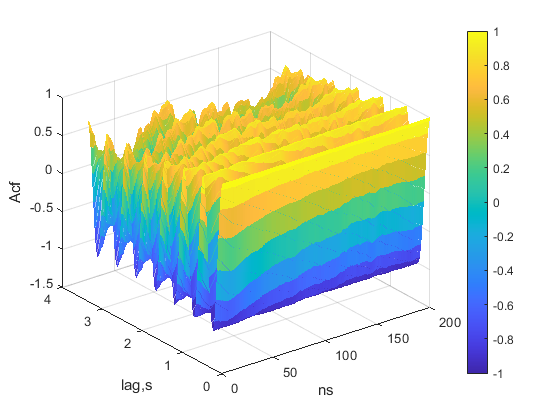

    lag  = floor(win/10); % наибольший лаг АКФ <= win/10
    lagS = 2*lag;
    ns=loadData(5,"ns");
    Time=loadData(5,"Time");
    Acf_sET12=loadData(5,"Acf_sET12");
    figure();
    set(gcf,'name','АКФ сингулярных троек sET12 сегментов pw'); clf;
    % mesh(ns,lgl,Acf_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    % xlabel("ns",'interp','none'); ylabel("lag",'interp','none');
    mesh(ns,Time,Acf_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    xlabel("ns",'interp','none'); ylabel("lag,s",'interp','none');
    zlabel("Acf",'interp','none'); grid on;

## Огибающие АКФ сингулярных троек sET12 сегментов pw - Picture 6

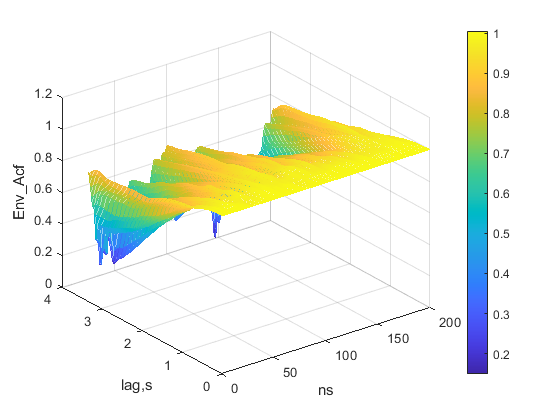

    ns=loadData(6,"ns");
    Time=loadData(6,"Time")';
    EnvAcf_sET12=loadData(6,"EnvAcf_sET12");
    figure();
    set(gcf,'name','Огибающие АКФ сингулярных троек sET12 сегментов pw');
    clf;
    % mesh(ns,lgl,EnvAcf_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    % xlabel("ns",'interp','none'); ylabel("lag",'interp','none');
    mesh(ns,Time,EnvAcf_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    xlabel("ns",'interp','none'); ylabel("lag,s",'interp','none');
    zlabel("Env_Acf",'interp','none'); grid on;

## Нормированные АКФ сингулярных троек sET12 сегментов pw - Picture 7

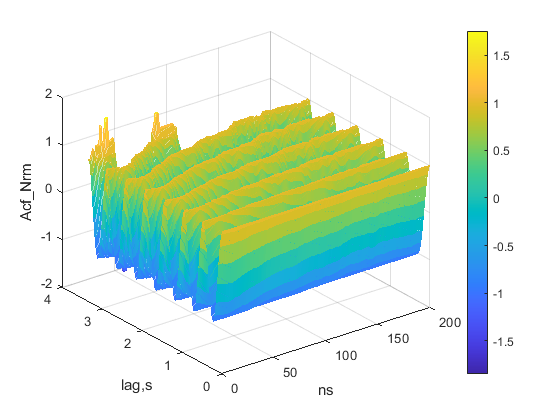

    ns=loadData(7,"ns");
    Time=loadData(7,"Time")';
    AcfNrm_sET12=loadData(7,"AcfNrm_sET12");
    figure();
    set(gcf,'name','Нормированные АКФ сингулярных троек sET12 сегментов pw');
    clf;
    % mesh(ns,lgl,AcfNrm_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    % xlabel("ns",'interp','none'); ylabel("lag",'interp','none');
    mesh(ns,Time,AcfNrm_sET12(1:lag,:),'FaceAlpha',0.5,'FaceColor','flat'); colorbar;
    xlabel("ns",'interp','none'); ylabel("lag,s",'interp','none');
    zlabel("Acf_Nrm",'interp','none'); grid on;

## Частоты нормир-ой АКФ сингуляр-х троек сегментов pw - Picture 8

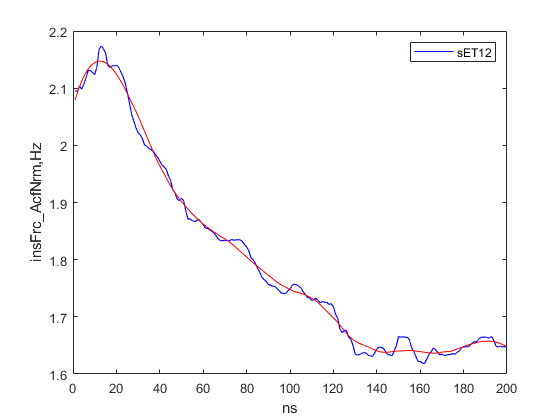

    ns=loadData(8,"ns");
    insFrc_AcfNrm=loadData(8,"insFrc_AcfNrm");
    smo_insFrc_AcfNrm=loadData(8,"smo_insFrc_AcfNrm")';
    figure();
    set(gcf,'name','Частоты нормир-ой АКФ сингуляр-х троек сегментов pw');
    clf;
    p1 = plot(ns,insFrc_AcfNrm,'b','LineWidth',0.8); hold on;
    plot(ns,smo_insFrc_AcfNrm,'r','LineWidth',0.4)
    % plot(ns,smo_insFrc_AcfNrm,'r','LineWidth',0.8); grid on; % smo_insFrc_AcfNrm
    xlabel("ns",'interp','none'); ylabel("insFrc_AcfNrm,Hz",'interp','none');
    legend(p1,'sET12');

## Периодограмма Томсона sET12 сегментов pw - Picture 9

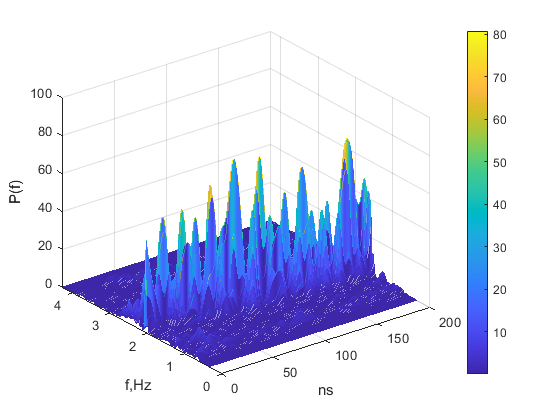

    figure();
    iGmin=loadVar(9,"iGmin");
    iGmax=loadVar(9,"iGmax");
    ns=loadData(9,"ns");
    pto_sET12=loadData(9,"pto_sET12");
    fG=loadData(9,"fG");
    set(gcf,'name','Периодограмма Томсона sET12 сегментов pw');
    clf;
    mesh(ns,fG(iGmin:iGmax),pto_sET12(iGmin:iGmax,:),'FaceAlpha',0.5,'FaceColor','flat');
    colorbar; grid on;
    xlabel("ns",'interp','none'); ylabel("f,Hz",'interp','none');
    zlabel("P(f)",'interp','none');

## Агрегирование сегментов очищенной пульсовой волны cpw - Picture 10

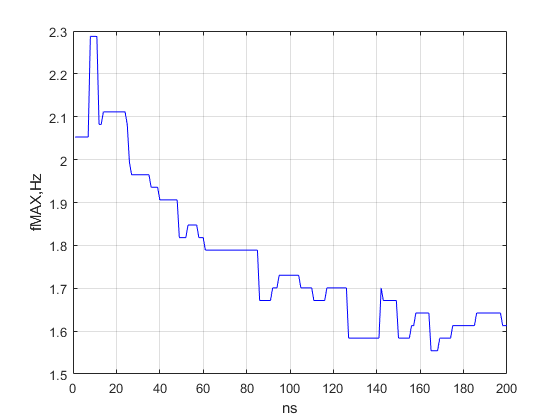

    figure();
    ns=loadData(10,"ns");
    pto_fMAX12=loadData(10,"pto_fMAX12");
    set(gcf,'name','Частоты основного тона sET сегментов pw');
    clf;
    plot(ns,pto_fMAX12,'b'); hold on; grid on;
    % plot(ns,smo_pto_fMAX12,'r','LineWidth',0.8); grid on;
    xlabel("ns",'interp','none'); ylabel("fMAX,Hz",'interp','none');